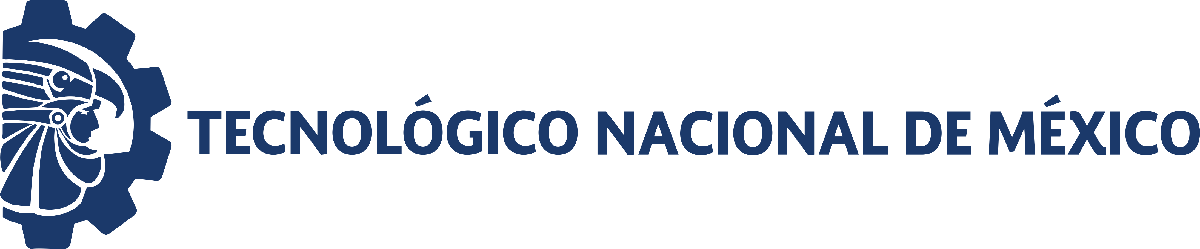                                 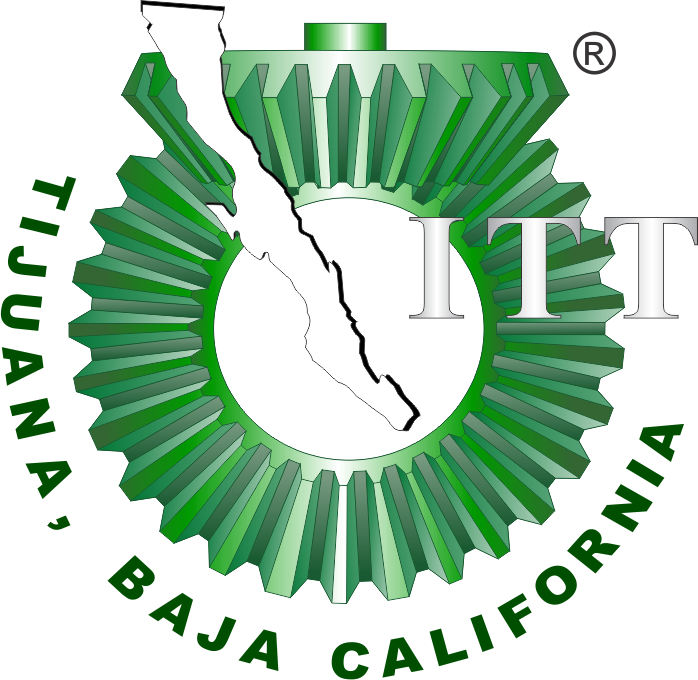

# Práctica 2: Sistema Cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

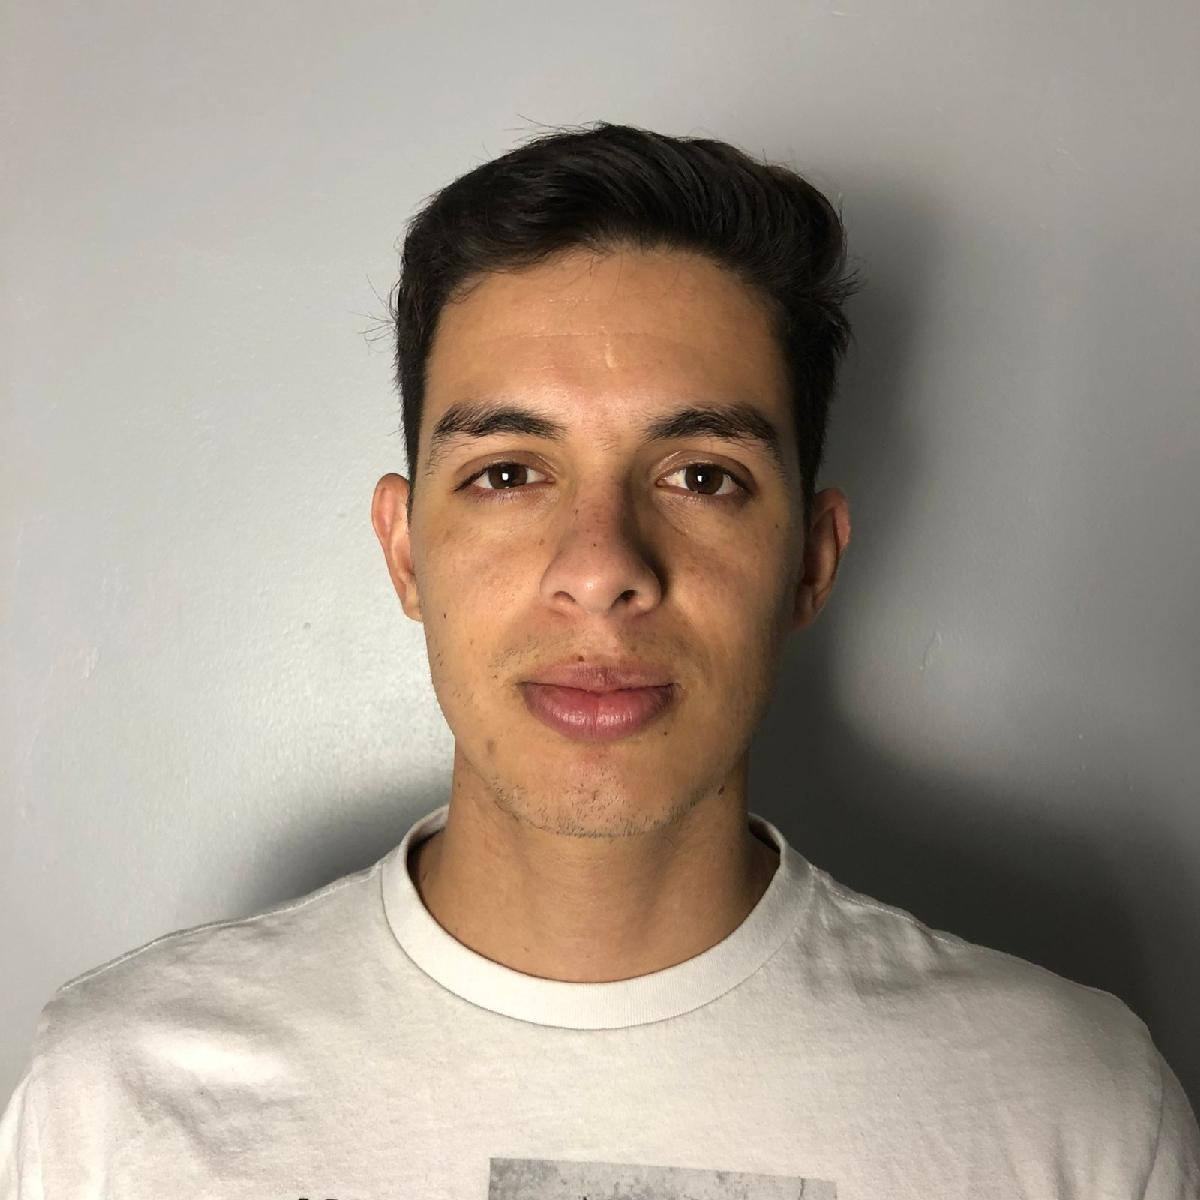

Nombre del alumno: Chizek Espinoza Josue

Número de control: 22212382

Correo institucional: l22212382**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Respuesta de sistema cardiovascular

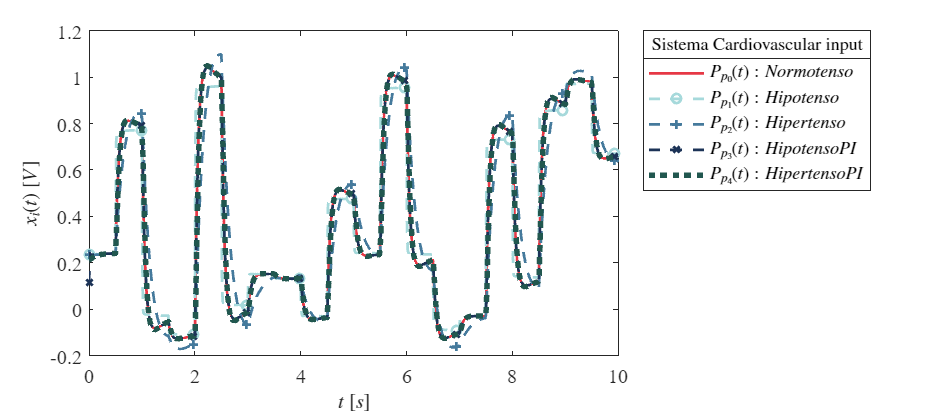

clc; clear; close all; warning('off','all')
tend = '10';
file = 'SistemaC';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';
Signal='Sistema Cardiovascular ';
set_param('SistemaC/Ppa(t)','Minimum','-0.2');
set_param('SistemaC/Ppa(t)','Maximum','1');
set_param('SistemaC/Ppa(t)','Seed','106');
set_param('SistemaC/Ppa(t)','SampleTime','0.5');
X = sim(file,parameters);
writematrix(X.Ppa,'signal.xlsx');
plotsignals(X.t,X.Pp0,X.Pp1,X.Pp2,X.Pp3,X.Pp4,Signal)

## Respuesta de la señal cardiovascular en lazo abierto

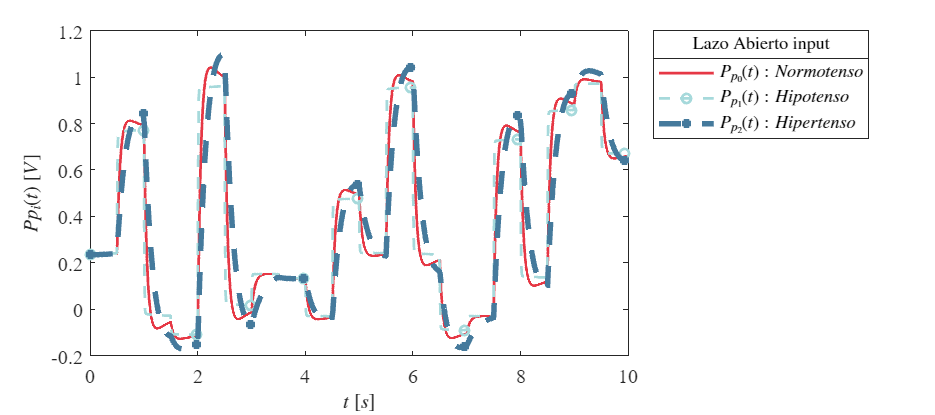

Signal = 'Lazo Abierto ';
set_param('SistemaC/Ppa(t)','Minimum','-0.2');
set_param('SistemaC/Ppa(t)','Maximum','1');
set_param('SistemaC/Ppa(t)','Seed','106');
set_param('SistemaC/Ppa(t)','SampleTime','0.5');
X1 = sim(file,parameters);
plotsignals2(X.t,X.Pp0,X.Pp1,X.Pp2,Signal)

## Respuesta de la señal cardiovascular en lazo cerrado

## Función: Respuesta a las señáles

function plotsignals(t, Pp0,Pp1, Pp2, Pp3, Pp4, Signal)
    set(figure(),'Color','w')
    set(gcf, 'units','centimeters', 'position', [1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on;grid off;box on;
    mycolors = [0.90,0.22,0.27;
                0.65,0.85,0.86;
                0.27,0.48,0.61;
                0.11,0.20,0.34;
                0.13,0.34,0.31;
                0.56,0.39,0.23];
    colororder(mycolors)
    
 
 p=plot(t, Pp0, '-', t, Pp1, '--o',t,Pp2, '--+',t,Pp3,'--x',t,Pp4,':', ...
       'LineWidth', 1.5,'MarkerSize',5, 'MarkerIndices',1:1000:length(t));
  set(p(5),'LineWidth',3);
   L = legend('$P_{p_0}(t): Normotenso$', '$P_{p_1}(t): Hipotenso$', '$P_{p_2}(t): Hipertenso$', '$P_{p_3}(t): HipotensoPI$','$P_{p_4}(t): HipertensoPI$');
   set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');
   title (L, [Signal, 'input'], 'FontSize',10)


    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$x_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)

    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','vector')
exportgraphics(gcf,[Signal,'.png'],'ContentType','vector')
end


function plotsignals2(t, Pp0,Pp1, Pp2, Signal)
   set(figure(), 'Color', 'w')
   set(gcf, 'units', 'centimeters', 'position', [1,1,18,8] )
   set(gca, 'FontName', 'Times New Roman', 'FontSize',11)
   hold on; grid off; box on;
   mycolors = [0.90,0.22,0.27;
                0.65,0.85,0.86;
                0.27,0.48,0.61;
                0.11,0.20,0.34;
                0.13,0.34,0.31;
                0.56,0.39,0.23];
   colororder(mycolors)

   p=plot(t, Pp0, '-', t, Pp1, '--o',t,Pp2, '--+', ...
       'LineWidth', 1.5,'MarkerSize',5, 'MarkerIndices',1:1000:length(t));
  set(p(3),'LineWidth',3);
   L = legend('$P_{p_0}(t): Normotenso$', '$P_{p_1}(t): Hipotenso$', '$P_{p_2}(t): Hipertenso$');
   set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');
   title (L, [Signal, 'input'], 'FontSize',10)


   xlabel('$t$ $[s]$', 'Interpreter','Latex', 'FontSize',11)
   ylabel('$Pp_i(t)$ $[V]$', 'Interpreter','Latex', 'FontSize',11)

exportgraphics(gcf,[Signal,'.pdf'],'ContentType','vector')
exportgraphics(gcf,[Signal,'.png'],'ContentType','vector')
end